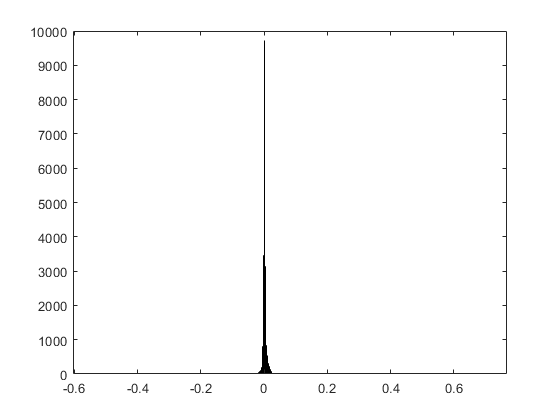

close all
clear all
frequencyoffsetnibble1=load('frequency_offset_nibble1.txt');
frequencyoffsetnibble2=load('frequency_offset_nibble2.txt');
frequencyoffsetnibble3=load('frequency_offset_nibble3.txt');
na_freq_nibble1=frequencyoffsetnibble1(:,2);
fit_freq_nibble1=frequencyoffsetnibble1(:,3);
na_freq_nibble2=frequencyoffsetnibble2(:,2);
fit_freq_nibble2=frequencyoffsetnibble2(:,3);
na_freq_nibble3=frequencyoffsetnibble3(:,2);
fit_freq_nibble3=frequencyoffsetnibble3(:,3);
freq_diff_nibble1=na_freq_nibble1-fit_freq_nibble1;
freq_diff_nibble2=na_freq_nibble2-fit_freq_nibble2;
freq_diff_nibble3=na_freq_nibble3-fit_freq_nibble3;

h1=histogram(freq_diff_nibble1);

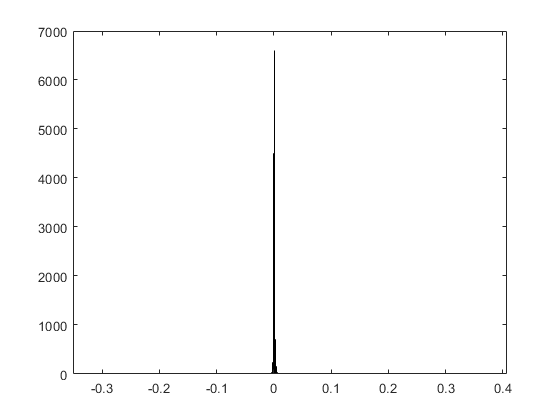

binlimits=h1.BinLimits;
min_x=binlimits(1);
max_x=binlimits(2);
x1=linspace(min_x, max_x, h1.NumBins);
y1=h1.Values/sum(h1.Values);

h2=histogram(freq_diff_nibble2);

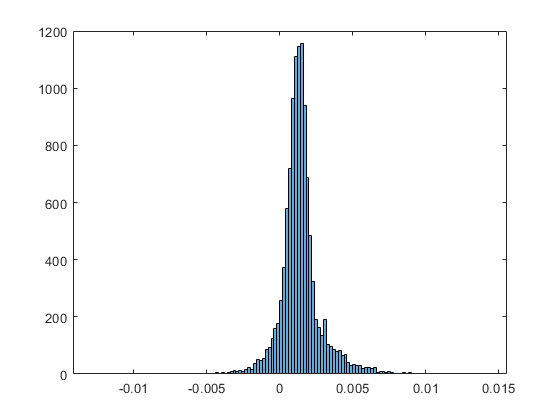

binlimits=h2.BinLimits;
min_x=binlimits(1);
max_x=binlimits(2);
x2=linspace(min_x, max_x, h2.NumBins);
y2=h2.Values/sum(h2.Values);

h3=histogram(freq_diff_nibble3);

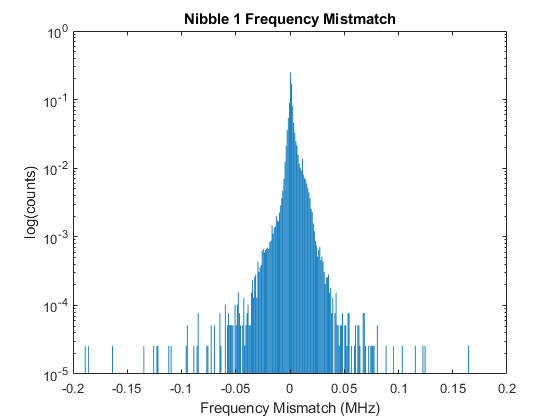

binlimits=h3.BinLimits;
min_x=binlimits(1);
max_x=binlimits(2);
x3=linspace(min_x, max_x, h3.NumBins);
y3=h3.Values/sum(h3.Values);

figure
bar(x1,y1)
set(gca, 'YScale', 'log')
axis([-0.2, 0.2, 0, 1])
axis 'auto y'
xlabel('Frequency Mismatch (MHz)')
ylabel('log(counts)')
title('Nibble 1 Frequency Mistmatch')

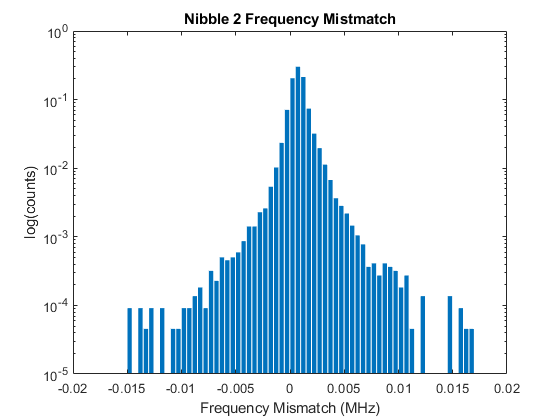


figure
bar(x2,y2)
set(gca, 'YScale', 'log')
axis([-0.02, 0.02, 0, 1])
axis 'auto y'
xlabel('Frequency Mismatch (MHz)')
ylabel('log(counts)')
title('Nibble 2 Frequency Mistmatch')

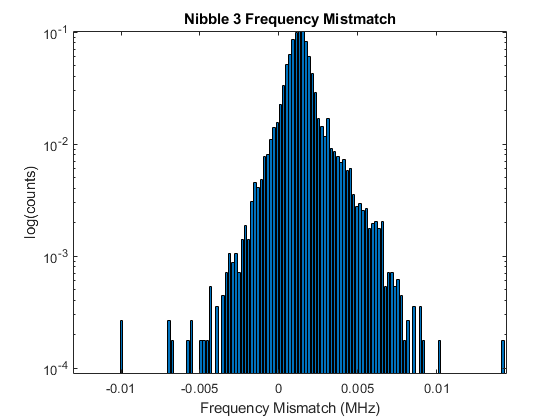


figure
bar(x3,y3)
set(gca, 'YScale', 'log')
xlabel('Frequency Mismatch (MHz)')
ylabel('log(counts)')
title('Nibble 3 Frequency Mistmatch')